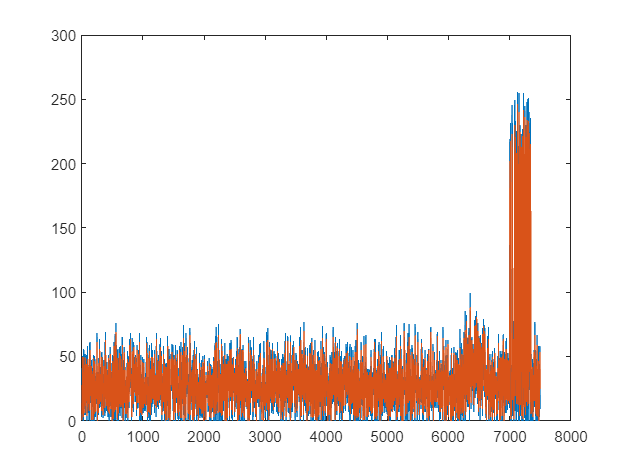

dataSend = "101101110101010101011000111";
ADCsignal2 = zeros(1, 10*750);
generuojama_amplitude_viso = 0.2:0.1:1.1;
generuojama_amplitude_viso = [zeros(1, 8), 0.15, 1];
for generuojama_amplitude_index = 1:10
    [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, generuojama_amplitude_viso(generuojama_amplitude_index));
    ADCsignal2(750*(generuojama_amplitude_index-1)+1:750*(generuojama_amplitude_index-1)+750) = ADCsignal;
end

ma = GenerateMA(ADCsignal2, 3);



plot(ADCsignal2)
hold on
plot(ma)
hold off